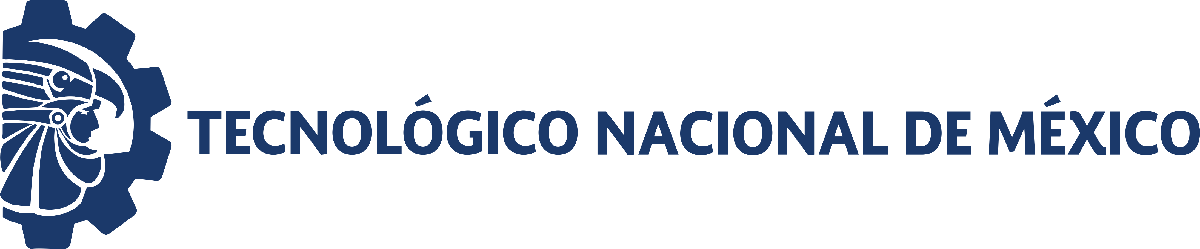                                 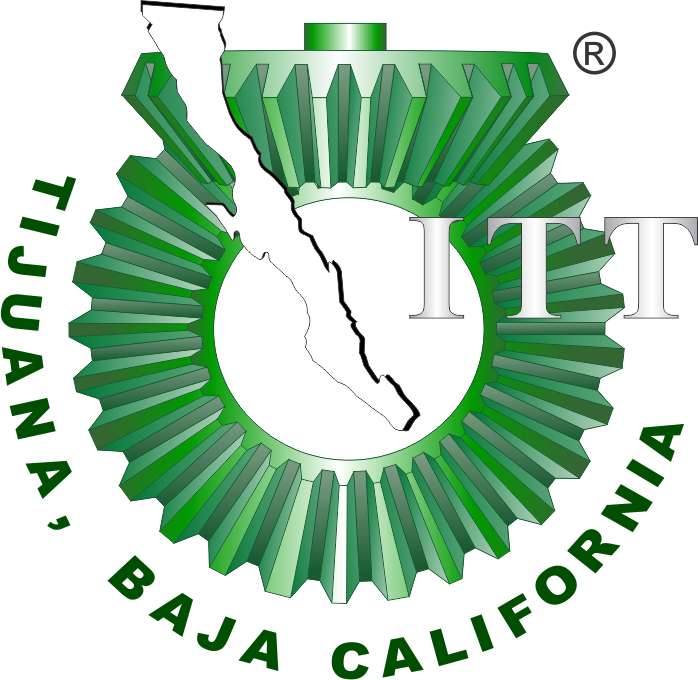

# Proyecto Final: “Representación del Asma mediante un Circuito Eléctrico RLC”

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

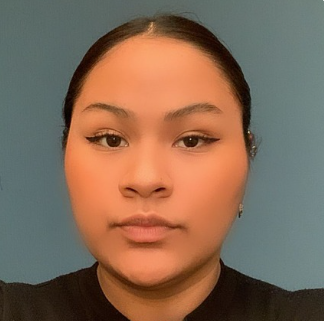

Nombre del alumno: Pamela Escobedo Sandoval

Número de control: 20211965

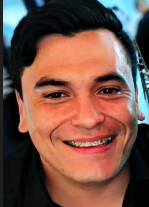

Nombre del alumno: Alan Omar Garcia Toledo 

Número de control: 20210787

Correo institucional: 20211965**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
file = 'Sistema';
open_system(file);
parameters.StopTime = '10';
parameters.Solver = 'ode15s';
parameters.MaxStep = '1e-3';
x = sim(file,parameters);
writematrix(x.Ve,'signal.xlsx');


## Respuesta del Sistema

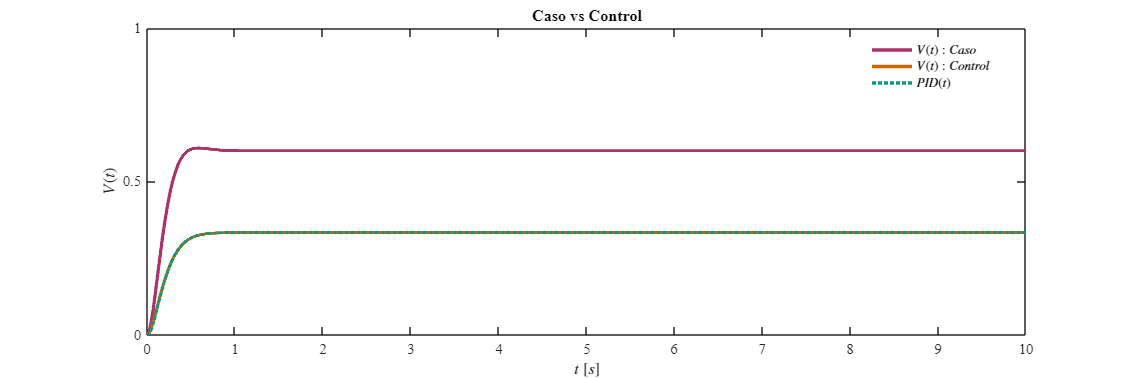

plotsignals(x.t, x.Vs4, x.Vs1, x.PID)

## Funcion Respuesta a las señales

function plotsignals(t, Vs4, Control, PID)

    set(figure(), 'Color', 'w')
    set(gcf, 'units', 'centimeters', 'position', [6, 6, 30, 10])

    colorgraficas = [0, 153, 136; 
                     204, 102, 0;
                     170, 51, 106]  / 255;

    box on; hold on;


    % Graficar todas las señales
    plot(t, Vs4, '-', 'LineWidth', 2.5, 'Color', colorgraficas(3,:), 'DisplayName', '$V(t):Caso $')
    plot(t, Control, '-', 'LineWidth', 2.5, 'Color', colorgraficas(2,:), 'DisplayName', '$V(t):{Control}$')
    plot(t, PID, ':', 'LineWidth', 2.5, 'Color', colorgraficas(1,:), 'DisplayName', '$PID (t)$')

    % Leyenda
    L = legend('Location', 'best');

    set(L, 'Interpreter', 'Latex', 'FontSize', 10, 'Box', 'off')

    % Etiquetas
    xlabel('$t$ $[s]$', 'Interpreter', 'Latex', 'FontSize', 11)
    ylabel('$V(t)$', 'Interpreter', 'Latex', 'FontSize', 11)

    % Límites
    xlim([0, 10]); xticks(0:1:10);
    ylim([0, 1]); yticks(0:0.5:1)

    % Título
    title('Caso vs Control', 'FontSize', 13)
    
    % Cuadrícula

    set(gca, 'FontName', 'Times New Roman', 'FontSize', 11)

    %% Exportar
    % exportgraphics(gcf, 'Control_Endocrino.pdf', 'ContentType', 'vector')
end

 disp(fieldnames(x))

    {'SimulationMetadata'}
    {'ErrorMessage'      }

